## Smoothing funkcija

function res = pogladkaj(vec, window_size)
    vec_len = length(vec); % dolzina vektorja

    if window_size < 7 || mod(window_size, 2) == 0
        disp('Dolzina window_size mora biti liha in večja od 7.');
        return
    end

    res = NaN(vec_len, 1);          % vektor za rezultate
    utezi = NaN(window_size, 1);    % vektor za uteži
    middle = ceil(window_size / 2); % sredina seznama uteži (ali window)

    % [[ INICIALIZACIJA UTEŽI ]]
    % izračunamo weights s pomočjo fibonacci funkcije
    % fib..(1) in fib..(2) vrneta 1, zato začnemo s fib..(2)
    for i = 1 : window_size
        utezi(i) = fibonacci(i + 1);
    end

    % shranimo polovico utezi, ker jih toliko potrebujemo za računanje
    utezi = utezi(1:middle);

    % [[ POGLADKAMO PODATKE ]]
    % poračunamo nove (smoothed) vrednosti, tako da gremo čez vse
    % vrednosti v vektorju. začnemo pri `sredinskem` elementu 
    % glede na middle in končamo vec_len - middle
    for i = middle : vec_len - middle + 1

        % loopamo čez vsak weight in poračunamo posamezno vrednost za neke 
        % elemente v vektorju s pomočjo window in jo dodamo v tmp
        tmp = 0;
        for j = 1 : length(utezi)
            if j == middle
                utezi = flip(utezi);
            end

            % prva iteracija: 3 + 1 - 3 = 1, torej dobimo prvi element
            cur_element = vec(i + j - middle); 
            cur_weight = utezi(j);
            tmp = tmp + cur_element * cur_weight;
        end

        % poračunamo povprečje vrednosti tega sliding window-a, kar
        % predstavlja novo vrednonst za naš podatek
        res(i) = tmp / sum(utezi);
    end
end

## Primer uporabe/dokaz delovanja

Preberemo in pripravimo podatke

temp = readtable('data.csv');
data = table2array(temp);
t = data(:, 1);   % time
x = data(:, 2);   % displacement
dt = t(2) - t(1); % neka razlika idk

Uporabimo funkcijo, da dobimo nove *poglajene* podatke.

window_size = 7; % za >=15 je vredu, za <=13 ni
x_smooth_3 = pogladkaj(x, window_size);

v___ = diff(x_smooth_3)/dt;
a___ = diff(v___)/dt;

v_smooth_3 = pogladkaj(v___, window_size);
a_smooth_3 = pogladkaj(a___, window_size);

Izrišemo grafe

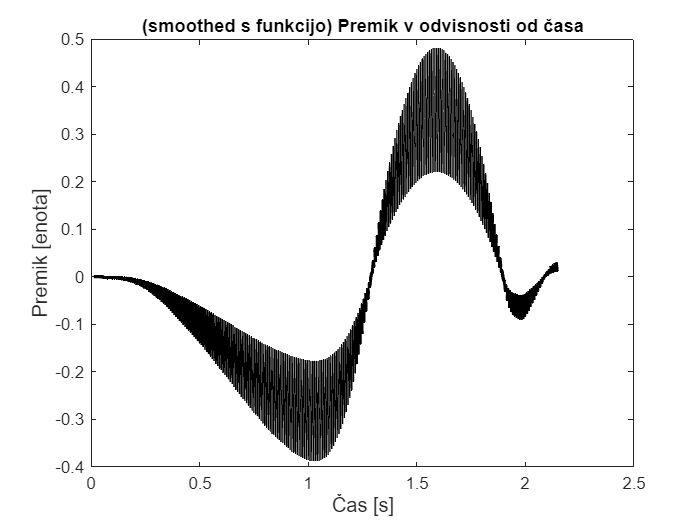

figure
plot(t, x_smooth_3, 'k', 'LineWidth', 2) % premik ~ čas
ylabel('Premik [enota]','FontSize',12)
xlabel('Čas [s]','FontSize',12)
title('(smoothed s funkcijo) Premik v odvisnosti od časa')

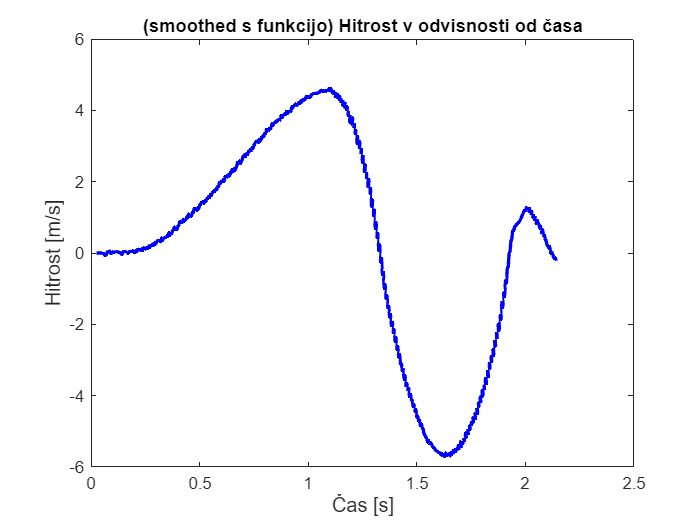


figure
plot(t(1:end - 1), v_smooth_3, 'b', 'LineWidth', 2) % hitrost ~ čas
ylabel('Hitrost [m/s]','FontSize',12)
xlabel('Čas [s]','FontSize',12)
title('(smoothed s funkcijo) Hitrost v odvisnosti od časa')

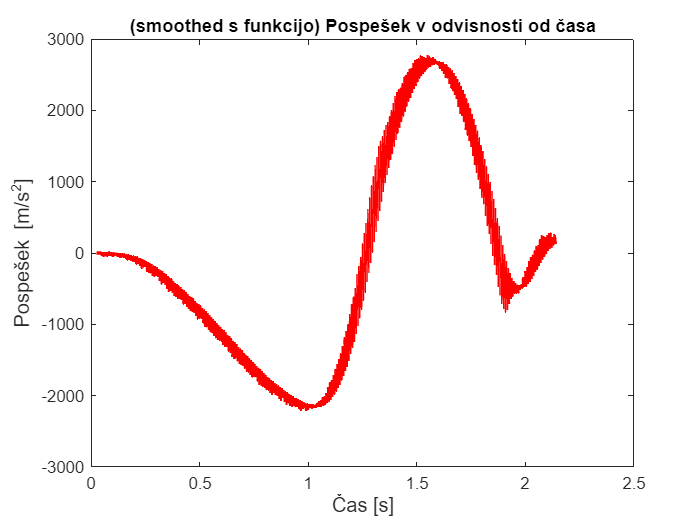


figure
plot(t(1:end - 2), a_smooth_3, 'r', 'LineWidth', 2) % pospešek ~ čas
ylabel('Pospešek [m/s^2]','FontSize',12)
xlabel('Čas [s]','FontSize',12)
title('(smoothed s funkcijo) Pospešek v odvisnosti od časa')